## Input runData and modelData

tic
%clear model;
% Settings to run model
runData.filename = 'testgif.gif';       % put in name of gif
runData.runType = 'time';
runData.oneGroup = true;
runData.adjointFlag = false;             % solving method: default = false
runData.checkGeometry = true;
runData.plotSolution = true;
runData.hmax = 0.05;                    % mesh size: default hmax = 0.05
runData.YZslice = 'optimize1';
runData.dataset = 'Temp_driven';  
runData.group = 1;          
runData.nEquations = 1;

% Load material properties and sources
[modelData.Heat,modelData.Heat_info] = h4_heatProperties_EK(runData.dataset);
% Material assignment to model domains
modelData.materialIDs = [1,2,2];        % define differently if different material per face (# faces = 3, so 3 elements)

% Source assignment to model domains
modelData.sourceIDs = [1,2,2];          % define differently if different source term (more heat /concentration)
modelData.seedheat = 10*1.066*60;       % specific heating power = SAR * conc. Max. concentration in seed is 1.5 *10^6 g/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 


## Create model, geometry and mesh

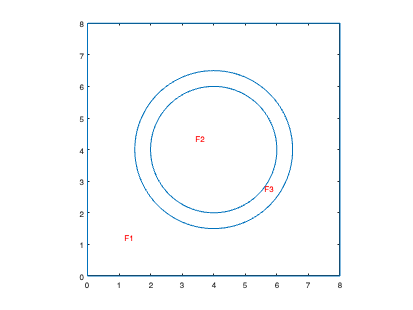

% Create PDE model
[model,modelData] = s1_createPDEModel(runData,modelData);
% Load test geometry
[model,~,centretumor,diametertumor] = t2_createGeometry2D(model,runData); % default = t2_creategeometry2D (circle tumor + part breast)

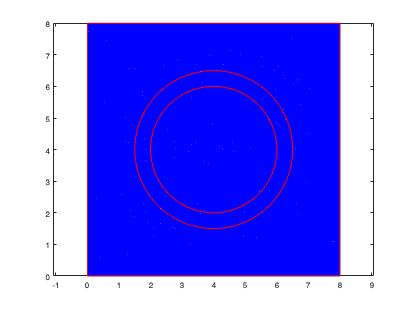

% Generate mesh
[model] = s3_createMesh2D(model,runData);

toc

Elapsed time is 46.542093 seconds.


## Set BC, IC and time scale

tic
% Boundary conditions:      only applicable for outer boundaries (no information on volume outside control volume)
runData.nBCs.neumann = 1;                                   % necessary to define if multiple neumann boundaries with different values
runData.BCs.neumann(1) = struct('edge',1:4,'q',0,'g',0);    % flux breast [#NPs/m2*s] % must depend on conc. present to not become negative. Which BC?
%runData.BCs.neumann(2) = struct('edge',[2 3],'q',0,'g',0); % flux tumor [#NPs/m2*s]
runData.nBCs.dirichlet = 1;
runData.BCs.dirichlet(1) = struct('edge',[],'u',0);         % [] means isempty

% Initial conditions
[modelData.x0, modelData.y0, noSeeds] = t4_3_YZ_seedlocationssquare(runData,diametertumor,centretumor);
runData.nICs = 1;                                           % necessary to define if multiple initial conditions different per face
modelData.Tinit = 310.15;                                   % temperature breast tissue
runData.IC(1) = struct('u',modelData.Tinit,'Face',1:3);     % initial temperature in body and tumour

m = 60;                                     % number of minutes % default total time  = 60 min
runData.timePoints = 0:0.1:m;               % timestep

% Loead BC and IC
[model] = s4_2_loadBCIC(model,modelData,runData);
toc

Elapsed time is 17.441698 seconds.


## Solve system of PDE 

tic
% Solve PDE model
[~,results] = h5_YZ_NPHeat2D(model,modelData,runData);
toc

Elapsed time is 222.623215 seconds.


modelData.Tresults = results.NodalSolution - 273.15;
Tresults = results.NodalSolution - 273.15;

## Results and plots: av/min/max temperature

% Calculate maximum, minimum and average results over time
tic
modelData.solMin = min(modelData.Tresults);
modelData.solMax = max(modelData.Tresults);
r = [2 , 2.5 , 3.5];  % Radius of tumour volume taken into account
[modelData] = h6_2_Tresults_average(model,modelData,r(1),r(2),r(3),centretumor(1)); % T values (max,min,average) in GTV

averageT_GTV = 114.1449

minT_GTV = 70.5349

maxT_GTV = 194.4126

averageT_PTV = 45.0650

minT_PTV = 37.1384

maxT_PTV = 75.0760

averageT_1cm = 42.0018

minT_1cm = 37.1384

maxT_1cm = 58.5226

[averageT,minT] = h6_2_Tresults_time(model,modelData,r(1),centretumor(1)); % averageT and minT only in tumour area

minT =    37.0000
   37.0000
   37.0000
   37.0000
   37.0003
   37.0015
   37.0051
   37.0124
   37.0260
   37.0466


averageT =    37.0000
   37.8627
   38.7249
   39.5851
   40.4429
   41.2978
   42.1488
   42.9953
   43.8360
   44.6708


solMax = modelData.solMax;                                                 % maxT in total area

t_back37 = 0

t_steady =    19.9000   20.0000   20.1000   20.2000   20.3000   20.4000   20.5000   20.6000   20.7000   20.8000   20.9000   21.0000   21.1000   21.2000   21.3000   21.4000   21.5000   21.6000   21.7000   21.8000   21.9000   22.0000   22.1000   22.2000   22.3000   22.4000   22.5000   22.6000   22.7000   22.8000   22.9000   23.0000   23.1000   23.2000   23.3000   23.4000   23.5000   23.6000   23.7000   23.8000   23.9000   24.0000   24.1000   24.2000   24.3000   24.4000   24.5000   24.6000   24.7000   24.8000



% plot
runData.timePointsX = 0:0.1:60;

Tresults_XZ_default = struct with fields:
    Tresults: [118097×601 double]
      Xnodes: [118097×1 double]
      Ynodes: [118097×1 double]
    averageT: [601×1 double]
        minT: [601×1 double]
      solMax: [37 46.0278 49.3085 51.2994 52.7418 53.8508 54.7604 55.5512 56.2711 56.8920 57.4812 58.0189 58.5233 59.0102 59.4715 59.9247 60.3619 60.7971 61.2238 61.6395 62.0442 62.4378 62.8205 63.2043 63.6314 64.0755 64.5155 64.9514 65.3832 65.8117 … ]


Tresults_YZ_default = struct with fields:
    Tresults: [118097×601 double]
      Xnodes: [118097×1 double]
      Ynodes: [118097×1 double]
    averageT: [601×1 double]
        minT: [601×1 double]
      solMax: [37 49.4233 56.7664 61.8643 65.7211 68.8153 71.4529 73.7213 75.7636 77.5853 79.2640 80.9328 82.5922 84.2259 85.8092 87.3486 88.8827 90.3890 91.8677 93.3391 94.7933 96.2297 97.6521 99.0600 100.4526 101.8282 103.1870 104.5297 105.8565 … ]


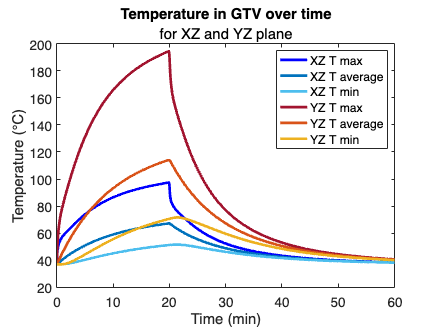

figure
plot(runData.timePointsX,Tresults_XZ_default.solMax,'LineWidth',3,'Color',"#0000FF")
hold on
plot(runData.timePointsX,Tresults_XZ_default.averageT,'LineWidth',3,'Color',"#0072BD")
plot(runData.timePointsX,Tresults_XZ_default.minT,'LineWidth',3,'Color',"#4DBEEE")
plot(runData.timePoints,Tresults_YZ_default.solMax,'LineWidth',3,'Color',"#A2142F")
plot(runData.timePoints,Tresults_YZ_default.averageT,'LineWidth',3,'Color',"#D95319")
plot(runData.timePoints,Tresults_YZ_default.minT,'LineWidth',3,'Color',"#EDB120")
set(gca,'FontSize',15)
title('Temperature in GTV over time','FontSize',22)
txt = {'for XZ and YZ plane'};
subtitle(txt,'FontSize',22)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',17)
xlabel("Time (min)",'FontSize',17) 
legend("XZ T max","XZ T average","XZ T min","YZ T max","YZ T average","YZ T min")

## Spread of heat: Intersection

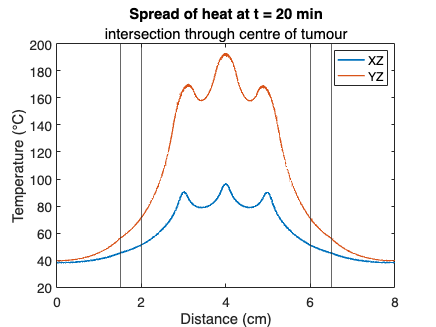

solMin = min(Tresults);
solMax = max(Tresults);
Xmesh = model.Mesh.Nodes(1,:);
Ymesh = model.Mesh.Nodes(2,:);
Xnodes = Xmesh';
Ynodes = Ymesh';
spread = Tresults_YZ_default.Tresults(:,201);
heatspread = [Tresults_YZ_default.Xnodes Tresults_YZ_default.Ynodes spread]
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.03 || heatspread(i,2) <= 3.97
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% standard %%%%%
spread = Tresults_XZ_default.Tresults(:,201);
heatspread_default = [Tresults_XZ_default.Xnodes Tresults_XZ_default.Ynodes spread];
for i = 1:length(heatspread_default(:,2))
    if heatspread_default(i,2) >= 4.03 || heatspread_default(i,2) <= 3.97
        heatspread_default(i,2) = 0;
    end
end
heatspread_default(any(heatspread_default(:,2)==0,2),:) = [];
heatspread_default = sortrows(heatspread_default,1);

figure
plot(heatspread_default(:,1),heatspread_default(:,3),'-','Linewidth',2)
hold on
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',1.5)
xline(2);
xline(6);
xline(1.5);
xline(6.5);

title('Spread of heat at t = 20 min','FontSize',22)
txt = {'intersection through centre of tumour'};
subtitle(txt,'FontSize',22)
ylabel(['Temperature (' char(176) 'C)'],'FontSize',17)
xlabel("Distance (cm)",'FontSize',17)
legend("XZ","YZ")

set(gca,'FontSize',15)

## Make graphs: profiles, intersection, over time

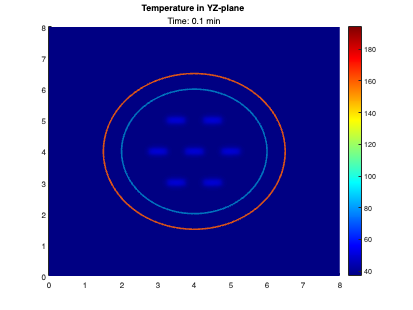

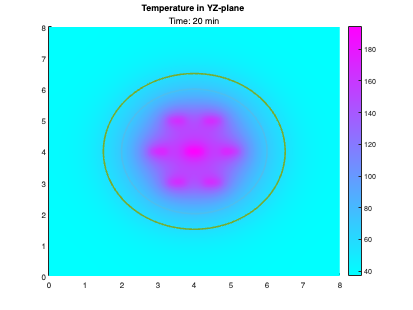

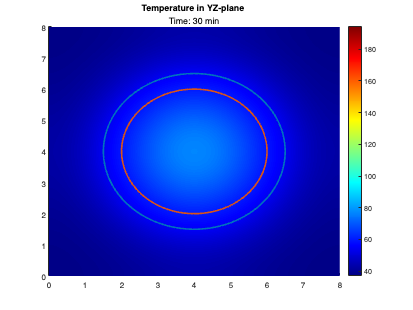

[model] = h6_results2D_YZ(model,modelData,runData);

% Save results
save Tresults_YZ_default Tresults solMax averageT minT Xnodes Ynodes

## Plot and gif solution

%s6_plotPDESolution(model,T,runData) %% --> not yet fixed for 3D